%% runOFDMReceiver.m – Minimal stand‑alone script to process an over‑the‑air OFDM capture
% -------------------------------------------------------------------------
% Assumptions
%   • All helper_*.m files shipped with the MathWorks example are **in the
%     same folder** as this script (or in a sub‑folder).  The first few
%     lines add that location to the MATLAB path automatically.
%   • You have a complex‑baseband capture saved in a MAT‑file, e.g.
%         rxCaptured.mat   → variable name  rxCaptured  (column vector)
%   • The capture was made with **identical RF/PHY settings** to the ones
%     hard‑coded below (FFT length, sub‑carrier spacing, CP, etc.).
%   • You only want to **receive / analyse** (no transmitter or channel
%     model).
% -------------------------------------------------------------------------

clc; clear; close all;

%% 0) Make sure the helper functions are on the MATLAB path
thisDir = fileparts(mfilename('fullpath'));
addpath(genpath(thisDir));   % recurse so sub‑folders work too

%% 1) High‑level receiver settings ----------------------------------------
userParam = struct( ...
    'BWIndex',          5, ...      % ⇐ MUST match the TX side
    'modOrder',         64, ...     % ⇐ “64QAM” captured waveform
    'codeRateIndex',    0, ...
    'numSymPerFrame',   15, ...
    'numFrames',        inf, ...    % "inf" = process until capture ends
    'fc',               902e6, ...
    'enableFading',     false, ...  % fading already baked in, if any
    'chanVisual',       "None", ...
    'enableCFO',        true, ...
    'enableCPE',        true, ...
    'enableScopes',     true, ...
    'verbosity',        1);

%% 2) Resolve all derived system parameters -------------------------------
[sysParam, ~] = helperOFDMSetParameters(userParam);
fsamp           = sysParam.scs * sysParam.FFTLen;        % Sample‑rate (Hz)
sampPerFrame    = (sysParam.FFTLen + sysParam.CPLen) ...
                  * sysParam.numSymPerFrame;

% Seed timingAdvance so the first buffer slice works
sysParam.timingAdvance = sampPerFrame;   % start one frame early

%% 3) Load the captured waveform from chanests folder ------------------
% Replace "22" with the desired file index if needed
rxFile = fullfile('chanests','22.mat');   % e.g., chanests/22.mat
rxVar  = 'chanEstCurrent';                 % variable inside each MAT

tmp    = load(rxFile, rxVar);
rxWave = double(tmp.(rxVar));              % full column vector

fprintf("Loaded %d samples from %s (%.3f s @ %.1f Msps)", ...
        numel(rxWave), rxFile, numel(rxWave)/fsamp, fsamp/1e6);

Loaded 38400 samples from chanests/22.mat (0.001 s @ 30.7 Msps)

fprintf("Loaded %d samples from %s (%.3f s @ %.1f Msps)\n", ...
        numel(rxWave), rxFile, numel(rxWave)/fsamp, fsamp/1e6);

Loaded 38400 samples from chanests/22.mat (0.001 s @ 30.7 Msps)



%% 4) Initialise receiver helper objects ----------------------------------
rxObj = helperOFDMRxInit(sysParam);

%% 5) Main processing loop -------------------------------------------------
ptr         = 1;          % Read pointer into rxWave
frameIdx    = 0;          % Counter for frames processed

% Pre-allocate sliding buffer (avoids persistent in script)
symLen   = sysParam.FFTLen + sysParam.CPLen;
frameLen = symLen * sysParam.numSymPerFrame;
sigBuf   = zeros(2*frameLen + 2*symLen, 1);  % column vector

CFO_log         = [];
chanEst_log     = {};
crcFailFrames   = 0;

while ptr + sampPerFrame - 1 <= length(rxWave)
    frameIdx = frameIdx + 1;
    sysParam.frameNum = frameIdx;  % required by helperOFDMRx
    frameSamps = rxWave(ptr : ptr + sampPerFrame - 1);
    ptr = ptr + sampPerFrame;

    %% Front‑end filtering + timing buffer --------------------------------
    % 1) Filter incoming chunk (ensure column)
    rxFiltered = rxObj.rxFilter(frameSamps(:));
    % 2) Slide buffer and append new samples
    sigBuf = [ sigBuf(frameLen+1 : 2*frameLen) ;
               rxFiltered ;
               zeros(symLen*2,1) ];
    % 3) Extract one frame (+ sync & ref guard) at current timing advance
    ta = sysParam.timingAdvance;
    span = frameLen + 2*symLen;
    rxIn = sigBuf( ta + (1:span) );

    %% Baseband receiver processing
    [rxBits, isConnected, toff, diags] = helperOFDMRx(rxIn, sysParam, rxObj);
    % Update timing advance (round & clamp)
    if isempty(toff), toff = sysParam.timingAdvance; end
    sysParam.timingAdvance = min(max(round(toff),1), frameLen);

    %% Diagnostics collection
    CFO_log      = [CFO_log; diags.estCFO(:)];
    chanEst_log{end+1} = diags.estChannel; %#ok<AGROW>
    if ~isempty(diags.dataCRCErrorFlag) && diags.dataCRCErrorFlag(end)
        crcFailFrames = crcFailFrames + 1;
    end

    if mod(frameIdx,10)==0
        fprintf("Processed %d frames...", frameIdx);
    end
end

.


fprintf("Finished – processed %d frames, CRC failed on %d frames.", ...
        frameIdx, crcFailFrames);

Finished – processed 1 frames, CRC failed on 0 frames.

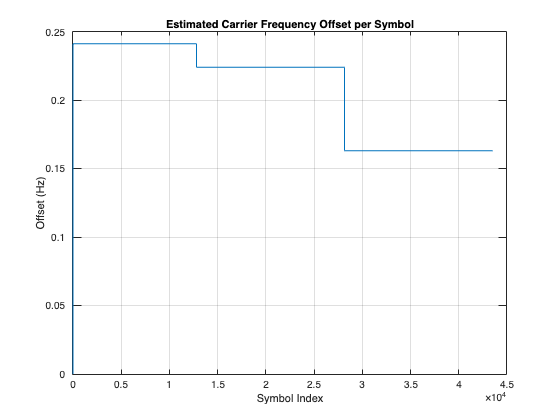


%% 6) Post‑run visualisations --------------------------------------------- ---------------------------------------------
if userParam.enableScopes && ~isempty(CFO_log)
    figure; plot(CFO_log * sysParam.scs);
    title("Estimated Carrier Frequency Offset per Symbol");
    xlabel("Symbol Index"); ylabel("Offset (Hz)"); grid on;
end


if ~isempty(chanEst_log)
    estChan = chanEst_log{end};
    if size(estChan,1) >= 3
        figure; plot(real(estChan(3,:))); hold on; plot(imag(estChan(3,:)));
        legend("Real","Imag"); xlabel("OFDM Symbol"); ylabel("H(sub‑3)");
        title("Channel estimate, subcarrier 3 – last frame"); grid on;
    else
        warning("Channel estimate only has %d subcarriers – skipping sub‑carrier plot.", size(estChan,1));
    end
end


% Uncomment to view the resource grid of *a* transmitted frame if you have of *a* transmitted frame if you have
% one available in variable  txGrid :
% helperOFDMPlotResourceGrid(txGrid, sysParam);
